Selection of Data from Database , 70% for Training and 30% for testing

clear;clc;


imds = imageDatastore('C:\flower Project\prcessedImage\', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\flower Project\prcessedImage\5663-zinnia-orange.jpg';
                              'C:\flower Project\prcessedImage\71K8SKRk4gL._SL1500_.jpg';
                              ' ...\prcessedImage\7dce6028-0e39-4c0a-aa06-2a5b26285f9a-45028f8.jpg'
                               ... and 6 more
                              }
                     Folders: {
                              'C:\flower Project\prcessedImage'
                              }
                      Labels: [prcessedImage; prcessedImage; prcessedImage ... and 6 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


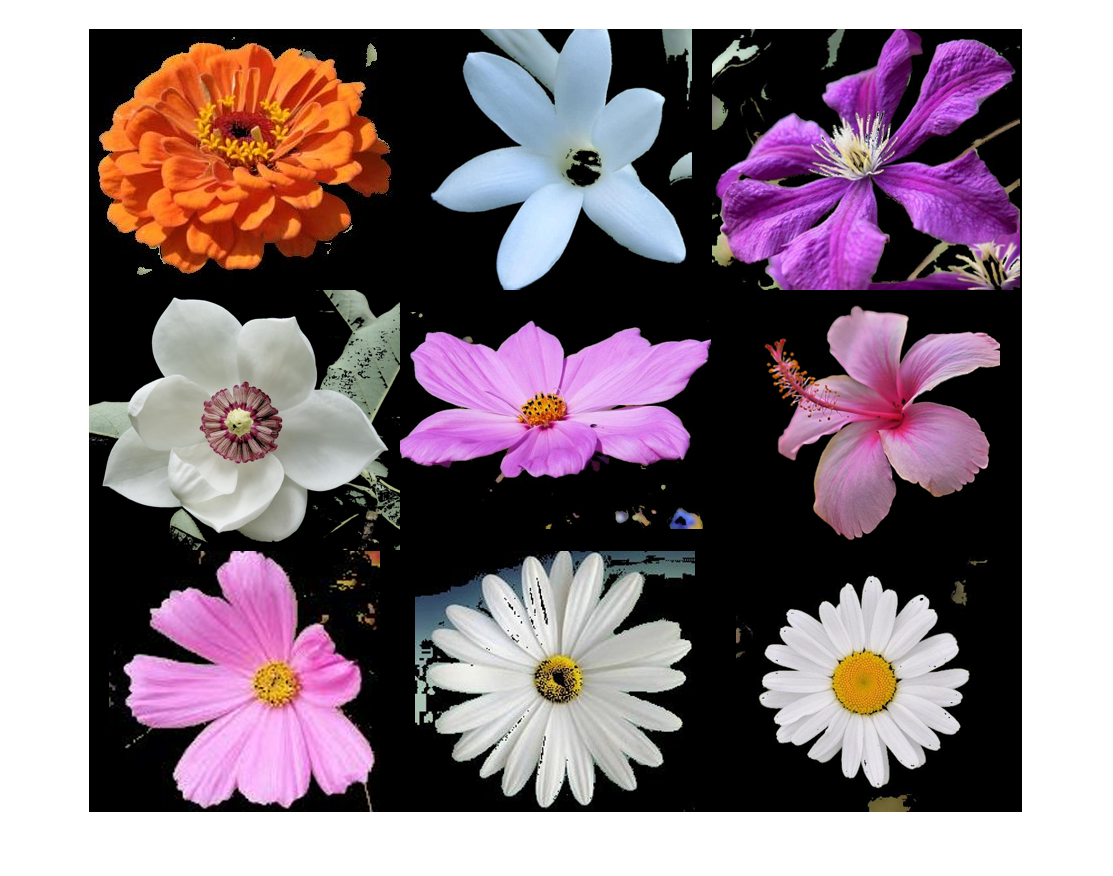


numImages = numel(imds.Labels);


for i = 1:numImages
    I{i} = readimage(imds,i);
end

figure
imshow(imtile(I))

Feature Extraction using GLCM and Red, Green , Blue average density

 [ TestSet] = FeatureExtractorFunction(imds)

TestSet = 9×10 table
    Contrast    Correlation    Energy     Homogenity      Red      std r      green     std g      blue      std b 
    ________    ___________    _______    __________    _______    ______    _______    ______    _______    ______

    0.27005       0.96048      0.19591     0.91691      0.77789     55.92    0.34385    44.364    0.15558    21.473
    0.14929       0.98967      0.30996      0.9795       0.6286    27.062    0.73361     30.79    0.81978    39.061
    0.46782       0.93268      0.18497     0.91233      0.59856    49.559    0.32709    50.418    0.64225    55.998
    0.17427       0.98584      0.23673     0.96783      0.

% [ TestSet] = FeatureExtractorFunction(imdsTest);
 load trainedClassifier
 YPred = trainedClassifier.predictFcn(TestSet)

YPred = 9×1 categorical array
     2 
     9 
     25 
     3 
     9 
     29 
     11 
     11 
     22 


load FlowerNet
augimds = augmentedImageDatastore([227 227 3],imds);
YPred = classify(FlowerNet,augimds)

YPred = 9×1 categorical array
     7 
     1 
     26 
     20 
     11 
     20 
     11 
     11 
     11 



queryno = 4;
BucketSize=10;
foldername = strcat('C:\flower Project\FLR_IMGS\',char(YPred(queryno)))

foldername = 'C:\flower Project\FLR_IMGS\20'

imdsDatabase = imageDatastore(foldername)

imdsDatabase =   ImageDatastore with properties:

                       Files: {
                              'C:\flower Project\FLR_IMGS\20\image00001.jpg';
                              'C:\flower Project\FLR_IMGS\20\image00002.jpg';
                              'C:\flower Project\FLR_IMGS\20\image00003.jpg'
                               ... and 97 more
                              }
                     Folders: {
                              'C:\flower Project\FLR_IMGS\20'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


[ TrainingSet] = FeatureExtractorFunction(imdsDatabase)

TrainingSet = 100×10 table
    Contrast    Correlation    Energy     Homogenity      Red      std r      green     std g      blue      std b 
    ________    ___________    _______    __________    _______    ______    _______    ______    _______    ______

    0.18894       0.96081      0.36165     0.94606      0.76422    50.937    0.19204    27.562    0.66002    52.278
    0.27681       0.97285      0.25586     0.93906      0.67566     37.08    0.54651     50.38    0.47319    38.731
    0.26075       0.97145       0.3706     0.94813       0.7399    41.947    0.48904    53.205    0.40471    37.032
    0.30543       0.96456      0.28774     0.93763  

[ TestSet] = FeatureExtractorFunction(imds);

**KD Tree Algorithm code Implementation**

**( **`'chebychev','cityblock','euclidean','minkowski')`

TrainData=table2array(TrainingSet);
TestData=table2array(TestSet);

`'minkowski' - method`

Mdl = KDTreeSearcher(TrainData,'Distance','minkowski','BucketSize',BucketSize)

Mdl =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'minkowski'
    DistParameter: 2
                X: [100×10 double]


IdxNN = knnsearch(Mdl,TestData(queryno,:),'K',8)

IdxNN =      9    90    50    40    60    80    20    30


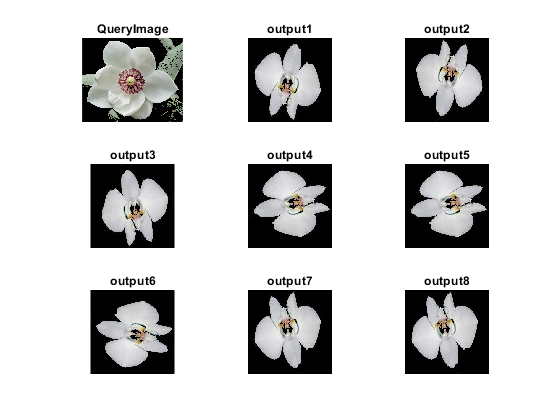


figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')

`'euclidean' - method`

Md2 = KDTreeSearcher(TrainData,'Distance','euclidean','BucketSize',BucketSize)

Md2 =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'euclidean'
    DistParameter: []
                X: [100×10 double]


IdxNN = knnsearch(Md2,TestData(queryno,:),'K',8)

IdxNN =      9    90    50    40    60    80    20    30



figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')

`'cityblock' - method`

Md3 = KDTreeSearcher(TrainData,'Distance','cityblock','BucketSize',BucketSize)

Md3 =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'cityblock'
    DistParameter: []
                X: [100×10 double]


IdxNN = knnsearch(Md3,TestData(queryno,:),'K',8)

IdxNN =      9    80    90    40    60    50    20    30


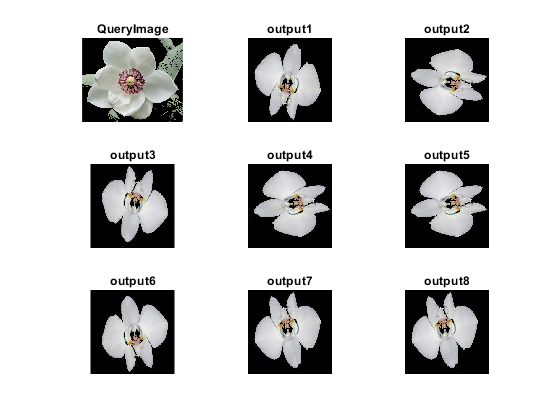


figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')

`'chebychev' - method`

Md4 = KDTreeSearcher(TrainData,'Distance','chebychev','BucketSize',BucketSize)

Md4 =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'chebychev'
    DistParameter: []
                X: [100×10 double]


IdxNN = knnsearch(Md4,TestData(queryno,:),'K',8)

IdxNN =      9    40    60    80    50    90    20    30


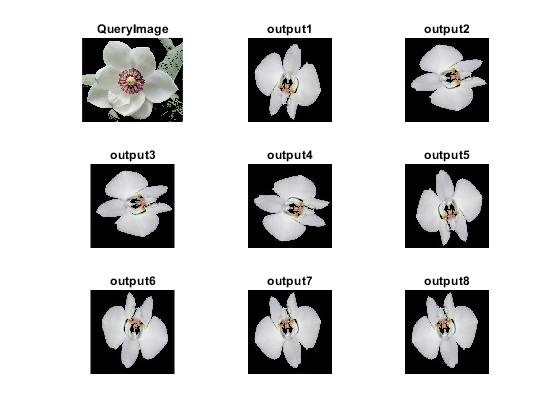


figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')